# Wind Turbine Aerodynamics

## Simplified representation

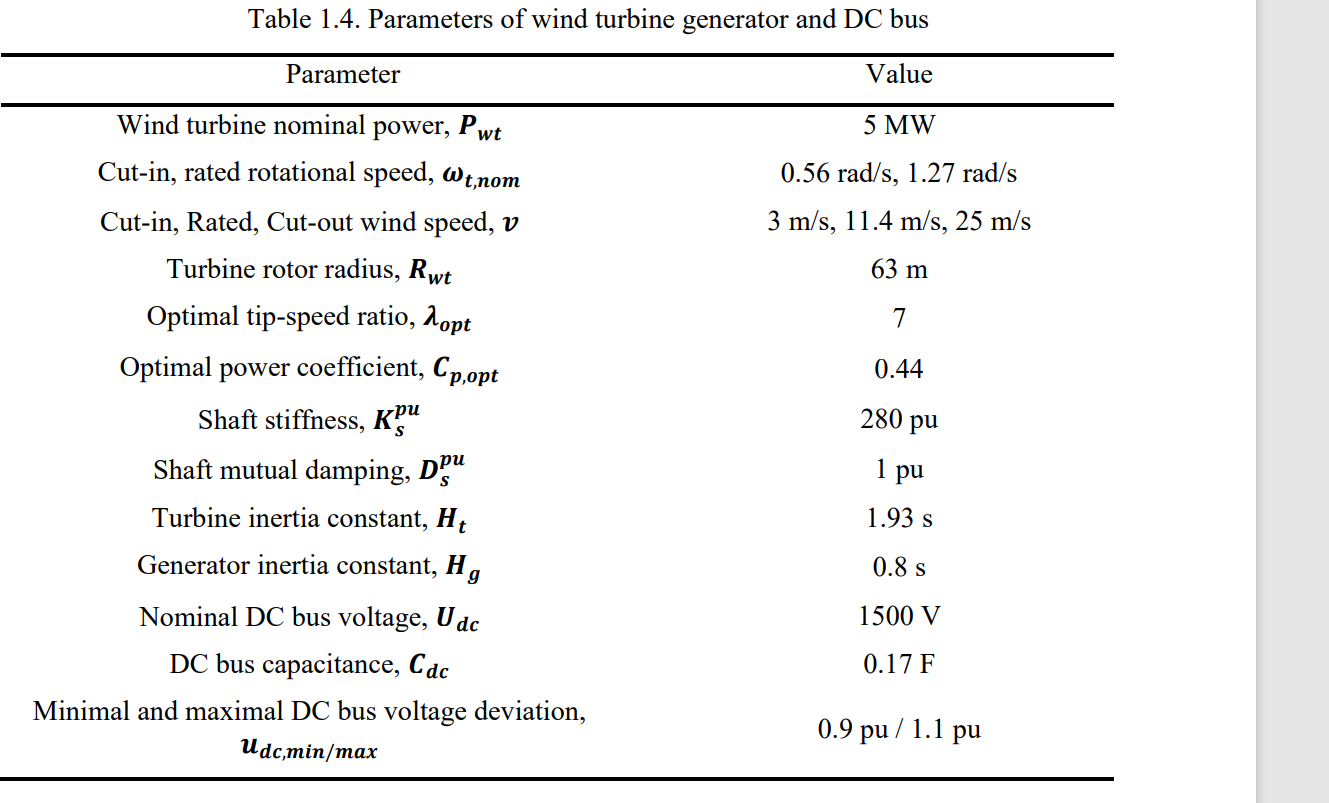

% 
omega_WTR = linspace(0.01,3,100); %*2*pi/60; % rad/s
omega_WTR_n = 1.27 % rad/s

omega_WTR_n = 1.2700

omega_WTR_min = 0.56 % rad/s

omega_WTR_min = 0.5600

R_WTR = 63; % m
v_w = linspace(3,22.8,100);% m/s   11.48;%
v_w_n = 11.4; % m/s
v_w_min = 3; % m/s




lambda = linspace(0,20,50) %omega_WTR.*R_WTR./v_w%

lambda =          0    0.4082    0.8163    1.2245    1.6327    2.0408    2.4490    2.8571    3.2653    3.6735    4.0816    4.4898    4.8980    5.3061    5.7143    6.1224    6.5306    6.9388    7.3469    7.7551    8.1633    8.5714    8.9796    9.3878    9.7959   10.2041   10.6122   11.0204   11.4286   11.8367   12.2449   12.6531   13.0612   13.4694   13.8776   14.2857   14.6939   15.1020   15.5102   15.9184   16.3265   16.7347   17.1429   17.5510   17.9592   18.3673   18.7755   19.1837   19.5918   20.0000


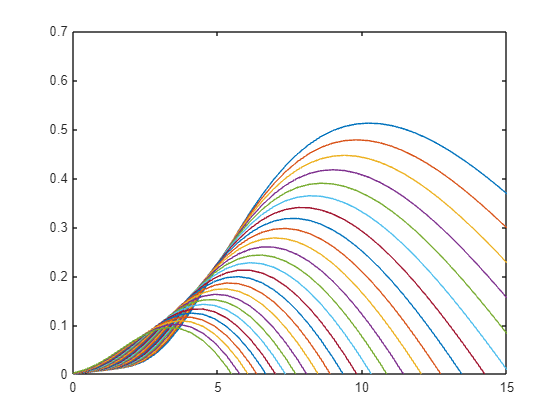

Theta_wr = linspace(0,25,26);

Theta_vw2 = 25;
lambda_opt = 7;

k_aero = -0.008;
c_aero = -0.0035;

v_omega_1 = 0.4; % pu
dpomega1 =0.7 ;
dpv1 = 1.6 ;
dpv2 = -3.5;

% P_wr = 0.5*rho*pi*R_wr^2*v_w^3*
% c_p_vector = zeros(1,length(lambda));
c_p_table = zeros(length(Theta_wr),length(lambda));
for j = 1:length(Theta_wr)
    c_p_vector = zeros(1,length(lambda));
    for i = 1:length(lambda)
        c_p_vector(i) = c_p(Theta_wr(j),lambda(i));
    end
    c_p_table(j,:) = c_p_vector;
    plot(lambda,c_p_vector)
    hold on
end

xlim([0 15])
ylim([0 0.7])
hold off



% initialization

P_aero_0 = 0.6; %p.u.
v_w_0 = 1+(1-0.3)/0.7*(P_aero_0-1) % Initial wind speed

v_w_0 = 0.6000

omega_WTR_0 = lambda_opt*v_w_n/(R_WTR*omega_WTR_n)*v_w_0

omega_WTR_0 = 0.5984

## Mechanical module


H_WTR = 2.5; % s
H_gen = 0.8; % s
c_drt = 1; % pu
k_drt = 280; % pu


## IEA 15 MW reference

% Per unit 
PerUnit

loadPowerCoefficient

Powercoefficient =     0.0073    0.0094    0.0115    0.0138    0.0160    0.0184    0.0207    0.0232    0.0256    0.0281    0.0307    0.0332    0.0357    0.0383    0.0407    0.0432    0.0456    0.0478    0.0499    0.0519    0.0537    0.0552    0.0565    0.0575    0.0582    0.0585    0.0585    0.0582    0.0575    0.0565    0.0551    0.0534    0.0514    0.0491    0.0465    0.0437
    0.0194    0.0235    0.0276    0.0317    0.0359    0.0401    0.0443    0.0485    0.0527    0.0567    0.0607    0.0646    0.0682    0.0716    0.0747    0.0775    0.0798    0.0817    0.0831    0.0840    0.0843    0.0841    0.0832    0.0818    0.0799    0.0774    0.0745    0.0710    0.0672    0.0631    0.0586    0.0538    0.0488    0.0435    0.0380    0.0324
    0.0409    0.0474    0.0539    0.0603    0.0667    0.0730    0.0791    0.0850    0.0907    0.0959    0.1007    0.1050    0.1086    0.1115    0.1137    0.1150    0.1155    0.1151    0.1137    0.1116    0.1086    0.1048    0.1004    0.0953    0.0898    0.083

loadPitchanglevector

Pitchanglevector =     -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


LoadTSRvector

TSRvector =     2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000




% Aerodynamics
% lille reference
% omega_WTR_n = 1.27 % rad/s
% omega_WTR_min = 0.56 % rad/s
% omega_WTR_sl = 1.20; % rad/s 
% R_WTR = 63; % m
% v_w_n = 11.4; % m/s
% v_w_min = 3; % m/s

% Mattia reference
% omega_WTR_n = 1.15*10.78*2*pi/60 % rad/s here it is the max rotor speed
% omega_WTR_min = 0.72*10.78*2*pi/60 % rad/s
% omega_WTR_sl = 1.05; % rad/s 
% R_WTR = 63; % m
% v_w_n = 14; % m/s
% v_w_min = 3; % m/s


% IEA 15 MW ref
omega_WTR_n = 7.56*2*pi/60 % rad/s here it is the max rotor speed

omega_WTR_n = 0.7917

omega_WTR_min = 5*2*pi/60 % rad/s

omega_WTR_min = 0.5236


R_WTR = 117; % m
v_w_n = 10.59; % m/s
v_w_min = 3; % m/s
v_w_max = 25;




Theta_vw2 = 25; % blade angle at twice the retad wind speed
lambda_opt = 8.8;
C_p_opt = 0.489;

% wind speed at nominal rotor speed
v_w_wrated = omega_WTR_n*R_WTR/lambda_opt

v_w_wrated = 10.5258

omega_WTR_sl = v_w_wrated*lambda_opt/R_WTR %0.78; % rad/s 

omega_WTR_sl = 0.7917

v_w_n*lambda_opt/R_WTR

ans = 0.7965

sl_ratio = omega_WTR_sl/omega_WTR_n;


k_aero = -0.008;
c_aero = -0.0035;

v_omega_1 = 0.4; % pu
dpomega1 =0.7 ;
dpv1 = 1.6 ;
dpv2 = -3.5;

vpo3 = (15e6*0.3/(0.5*pi*R_WTR^2*1.225*0.51))^(1/3)

vpo3 = 6.9450

vpo3_pu=vpo3/v_w_n

vpo3_pu = 0.6558



P_aero_0 = 0.6; %p.u.
v_w_0 = 1+(1-vpo3_pu)/0.7*(P_aero_0-1) % Initial wind speed

v_w_0 = 0.8033

omega_WTR_0 = lambda_opt*v_w_n/(R_WTR*omega_WTR_n)*v_w_0 % Initial rotation

omega_WTR_0 = 0.8082

omega_WTR_sl0 =sl_ratio*omega_WTR_0;

## Drive train

J_rigid = 3.524605e8;
damping = 4.457e-4;
H_rigid = 3%0.5*J_rigid*omega_s_m_base/(15e6)

H_rigid = 3

% k_drt = 25 %damping*T_base/omega_s_m_base


H_ratio = 0.3

H_ratio = 0.3000

H_WTR = H_rigid*(1-H_ratio) % s

H_WTR = 2.1000

H_gen = H_rigid*H_ratio % s

H_gen = 0.9000

c_drt = 1; % pu
k_drt = 280; % pu

## Generator spec

P_rated = 15e6 ;% 

L_d = 0.04444160004/L_s_base; % H divided by Base H
L_q = L_d;
R_a = 0.16/Z_s_base; % Ohm divided by Base Z
psi_pm = 0.1168501600/V_s_base; % Wb divided by base V

X_d = L_d*L_s_base*omega_s_e_base/Z_s_base;

v_t = 1; i_t = 0.6;

% initial values
% power factor
phi = acos(0.5/0.6);
% voltage angle
delta_0 = -atan((X_d*i_t*cos(phi)-R_a*i_t*sin(phi))/(v_t+R_a*i_t*cos(phi)+X_d*i_t*sin(phi)))

delta_0 = -0.2935


v_d0 = v_t*cos(delta_0)

v_d0 = 0.9572

v_q0 = v_t*sin(delta_0)

v_q0 = -0.2893

i_d0 = i_t*cos(delta_0+phi) % pu

i_d0 = 0.5746

i_q0 = i_t*sin(delta_0+phi) % pu

i_q0 = 0.1728

omega_me0 = omega_WTR_0; % pu



## Pitch controller

T_pitch  = 2.2 % [s], Blade angle controller time constant

T_pitch = 2.2000

T_servo = 0.1 % [s], Servo Time constant

T_servo = 0.1000

K_pitch = -38.6 % [deg/s] Blade angle controller gain

K_pitch = -38.6000

pitch_min = 0 % [deg] min blade angle

pitch_min = 0

rate_min = -10 % [deg/s] closing rate of change limit

rate_min = -10

pitch_max = 30 % [deg] max blade angle

pitch_max = 30

rate_max = 10 % [deg] opening rate of change limit

rate_max = 10

omega_ref = 1 % [pu]

omega_ref = 1

## simtime

simtime = 60

simtime = 60

## Wind ramp

t_init_done = 50

t_init_done = 50

t_ramp = 35

t_ramp = 35

wind_ramp = linspace(v_w_0,1,t_ramp);
time_wind_ramp = linspace(t_init_done+1,t_ramp+t_init_done+1,t_ramp);

wind_array = [0 time_wind_ramp  simtime; v_w_0 wind_ramp wind_ramp(end)]'

wind_array =          0    0.8033
   51.0000    0.8033
   52.0294    0.8091
   53.0588    0.8149
   54.0882    0.8207
   55.1176    0.8265
   56.1471    0.8322
   57.1765    0.8380
   58.2059    0.8438
   59.2353    0.8496


## Wind Steps

t_init_done = 5

t_init_done = 5


n_step = 7

n_step = 7


t_step = (simtime-t_init_done)/n_step

t_step = 7.8571

wind_step = linspace(v_w_0,1.5,n_step)

wind_step =     0.8033    0.9194    1.0355    1.1517    1.2678    1.3839    1.5000


time_wind_step = linspace(t_init_done+1,t_step*n_step+t_init_done+1,n_step);

wind_array_step = [ time_wind_step  time_wind_step(end)+0.0001; wind_step wind_step(end)]

wind_array_step =     6.0000   15.1667   24.3333   33.5000   42.6667   51.8333   61.0000   61.0001
    0.8033    0.9194    1.0355    1.1517    1.2678    1.3839    1.5000    1.5000



% c = [0.645 116 0.4 5 21 0.00912 0.08 0.035 0.001]
% U = 6
% omega = 1
% R = 63
% lambda = omega*R/U
% beta=0
% 
% a = (-c(4)-c(3)*(2.5+beta)+c(2)*1/(lambda+c(7)*(2.5+beta))-c(8)/(lambda+(2.5+beta)^3))
% exponent = c(5)*1/(lambda+c(7)*(2.5+beta))-c(8)/(lambda+(2.5+beta)^3)
% cp = c(1)*(c(6)*lambda+a/exp(exponent))+c(9)*lambda



function x = c_p(Theta,lambda)
    % % Fortman
    % c = [0.297 118 -0.50 0.922 1.12 3.33 15.6 0.102 0.017 0.751]';
    % Theta_mark = Theta*c(10);
    % lambda_i = (1/(lambda+c(8)*Theta_mark)-c(9)/(Theta_mark^3+1))^(-1);
    % x = c(1)*(c(2)/lambda_i-c(3)*Theta_mark-c(4)*Theta_mark^(c(5))-c(6))*exp(c(7)/lambda_i);
    % 
    
    % % Mattia
    % c = [0.645 116 0.4 5 21 0.00912 0.08 0.035 0.001];
    % x = c(1)*(c(6).*lambda+(-c(4)-c(3).*(2.5+Theta)+c(2)*1./(lambda+c(7)*(2.5+Theta)-c(8)./(lambda+(2.5+Theta)^3))./(exp(c(5)*(1./(lambda+c(7)*(2.5+Theta)-c(8)./(lambda+(2.5+Theta)^3)))))))+c(9)*lambda;
    % % Johan
    % c = [0.37 151 0.58 0.002 2.14 13.2 -18.4 0.1 0.003 3]';
    % lambda_i = 1./(lambda-c(8)*Theta)-c(9)/(Theta^(c(10))+1);
    % x = c(1)*(c(2)./lambda_i-c(3)*Theta-c(4)*Theta^(c(5))-c(6)).*exp(c(7)./lambda_i);
    % % 'Mattia 2
    c = [0.645 116 0.4 5 21 0.00912 0.08 0.035 0.001];
    a = (-c(4)-c(3)*(2.5+Theta)+c(2)*1/(lambda+c(7)*(2.5+Theta))-c(8)/(lambda+(2.5+Theta)^3));
    exponent = c(5)*1/(lambda+c(7)*(2.5+Theta))-c(8)/(lambda+(2.5+Theta)^3);
    x = c(1)*(c(6)*lambda+a/exp(exponent))+c(9)*lambda;

end